# Stima Giunto 1 su SCARA. 

Modello giunto 1

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

system=ElasticRoboticSystem();
st=system.getSamplingPeriod;
system.show

This system has 4 outputs:
- position_1
- position_2
- velocity_1
- velocity_2
This system has 2 inputs:
- torque_1, with maximum limit = 600.000000
- torque_2, with maximum limit = 600.000000


ans =   ElasticRoboticSystem with no properties.

cs=ControlledSystemScara(system,'n');


%ctrl=SimpleScaraController(cs.getSamplingPeriod);
ctrl =ScaraBasicPIController(st,0.01,0.1,0.01,0.1)

ctrl =   ScaraBasicPIController with no properties.

cs.setController(ctrl);

## Identificazione

Definisco segnale di identificazione

omega_portante=0.1;%0.1
ampiezza_portante=30;%30
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Segnale eccitante

w0=1; %rad/s
w1=pi/(st); %rad/s
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

ampliezza_identificazione=80;

#### sommo = Portante + Segnale eccitante

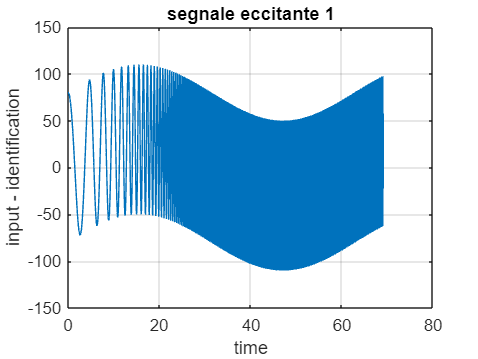

exciting_signal1=zeros(length(t),system.getInputNumber);
exciting_signal1(:,1)=portante+ control_action_identificazione*ampliezza_identificazione;

figure
plot(t,exciting_signal1(:,1))
title('segnale eccitante 1')
xlabel('time')
ylabel('input - identification')
grid on

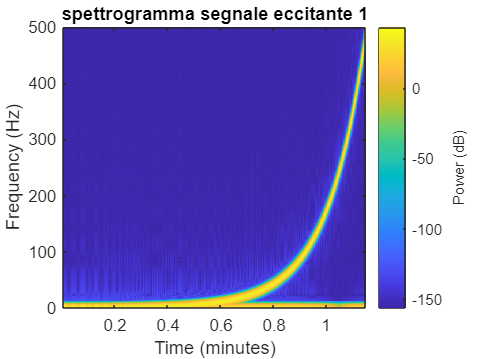

figure
pspectrum(exciting_signal1(:,1),1/st,'spectrogram');
title('spettrogramma segnale eccitante 1')

### Simulo il sistema

cs.initialize % reinizializza la simulatione

%cs.setRestTime(1); % attendi di stabilizzarti
%cs.moveTo([0 0]); % cambia punto di lavoro robot sbracciato
%valore giunto 1 e giunto 2 in radianti
measure = system.computeOutput;

reference = zeros(length(t),6); % 2*(pos,vel,acc)
reference(:,1) = measure(1);
reference(:,2) = measure(2);

for idx=1:length(t)
        % step: simulo il sisteme in anello chiuso
        [process_output(idx,:),control_action(idx,:),t(idx,1)]=cs.step(reference(idx,:)',exciting_signal1(idx,:)');  
        % ingresso 1: riferimento
        % ingresso 2: segnale a valle del controllore
end

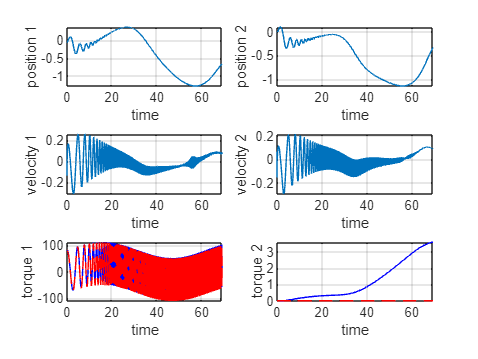

figure(1)
subplot(3,2,1)
plot(t,process_output(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,process_output(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,control_action(:,1),'-b',t,exciting_signal1(:,1),'--r')
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,process_output(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,process_output(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,control_action(:,2),'-b',t,exciting_signal1(:,2),'--r')
xlabel('time')
ylabel('torque 2')
grid on

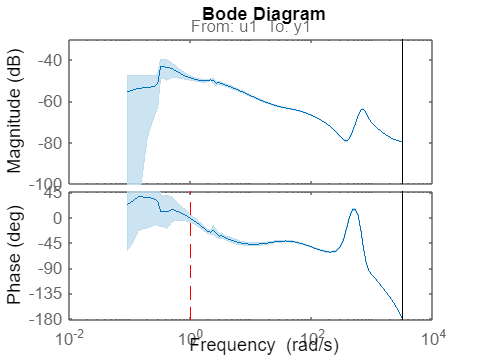

identification_1= iddata(process_output(:,3),exciting_signal1(:,1),st);
freq_resp1=spafdr(identification_1); % La funzione spafdr restituisce una risp freq e una incertezza come oggetto di tipo IDFRD
figure
bode_line=bodeplot(freq_resp1); %bode del sistema
showConfidence(bode_line,3);
%plotto la frequenza di inizio del segnale eccitante
hold on
plot(w0*[1 1],ylim,'--r')
hold off

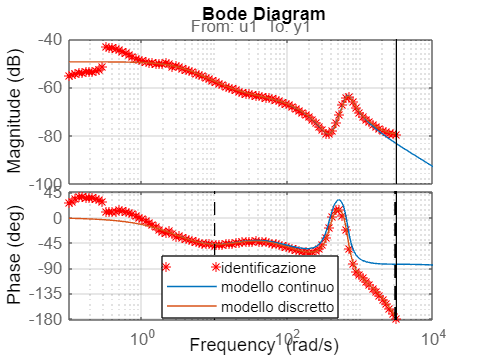


%% Stima del primo modello 
% Aggiunto dei pesi
peso=ones(length(freq_resp1.Frequency),1);
wpeso0=10;
wpeso1=3000;

peso(freq_resp1.Frequency<=wpeso0)=1e-5;
peso(freq_resp1.Frequency>=wpeso1)=1e-5;

opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello1_con=ssest(freq_resp1,5,opts);% il coefficiente 3 rap. l'ordine del modello
modello1_dis=ssest(freq_resp1,5,'Ts',st,opts);

% Grafico modelli
figure
bode_opts=bodeoptions('cstprefs');
bode_opts.PhaseWrapping='off';


h1=bodeplot(freq_resp1,'r*',bode_opts);
hold on
bode(modello1_con,modello1_dis,bode_opts);

%visualizzo il range di frequenze di interesse
xlim([w0 w1])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

hold off
grid on
xlim([1e-1 1e4])
legend('identificazione','modello continuo','modello discretto','Location','best')

## Validazione

Cambio portante e segnale eccitante

omega_portante_v=0.05;
ampiezza_portante_v=50;
T_portante_v=2*pi/omega_portante_v;

scelgo una lunghezza dell'esperimento di almeno un periodo della portante.

t_v=(0:st:(1.1*T_portante_v))';
portante_v=ampiezza_portante_v*sin(2*pi/120*t_v);

Dopo di che posso andare a definire il segnale eccitante, che partirà da una frequenza maggiore (almeno un decade).

w0_v=1; %rad/s
w1_v=2*pi/st; %rad/s
control_action_validazione = chirp(t_v,w0_v/2/pi,t_v(end),w1_v/2/pi, 'logarithmic');%per cambiare in maniera significativa per validare il modello.
ampliezza_validazione=75;%occhio al valore per non sbattere

Sommo i due segnali

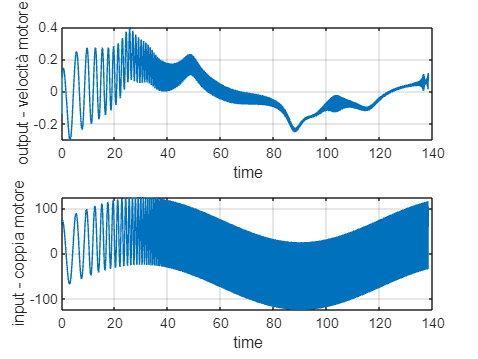

exciting_signal1_v = zeros(length(t_v),system.getInputNumber);
exciting_signal1_v(:,1)=portante_v+ control_action_validazione*ampliezza_validazione;
cs.initialize

for idx=1:length(t_v)
    [process_output_v(idx,:),t_v(idx,1)]=cs.openloop(exciting_signal1_v(idx,:));
end
figure
subplot(2,1,1)
plot(t_v,process_output_v(:,3))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t_v,exciting_signal1_v(:,1))
xlabel('time')
ylabel('input - coppia motore')
grid on

### Validazione in frequenza

validation=iddata(process_output_v(:,3),exciting_signal1_v(:,1),st);
freq_resp_vali = spafdr(validation);
figure
bode(freq_resp_vali,freq_resp1,bode_opts)

Plotto la frequenza di inizio del segnale eccitante

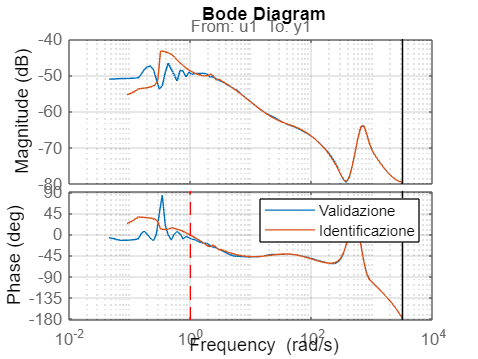

hold on
plot(w0_v*[1 1],ylim,'--r')
hold off
grid on
legend('Validazione','Identificazione')

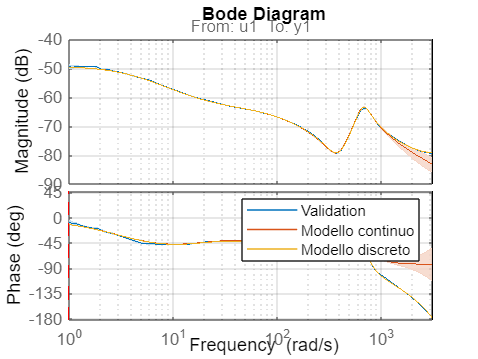


figure
h=bodeplot(freq_resp_vali, bode_opts);
hold on
showConfidence(h,3)
bode(modello1_con,modello1_dis, bode_opts)
xlim([w0 w1])
plot(w0_v*[1 1],ylim,'--r')
hold off
grid on

legend('Validation','Modello continuo','Modello discreto')

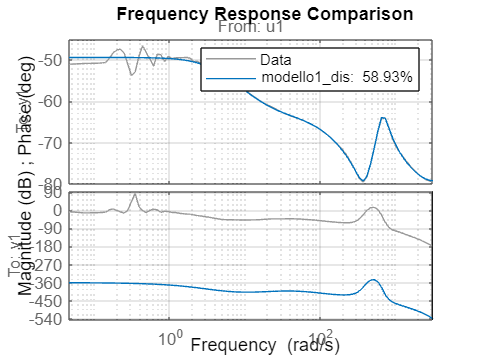

figure 
compare(freq_resp_vali,modello1_dis)
grid on